clear all
close all 
mask_struct = open("image_data_mask.mat");
image_struct = open("image_data.mat");


mask_img = mask_struct.out.image_data_masked;
whole_img =  mask_struct.out.image_data;

figure(1);
for i = 1:101
    imshow(whole_img(:,:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end
figure(2)
for i = 1:101
    imshow(mask_img(:,:,i));  % Added the closing parenthesis
    pause(0.2);  % Pauses for 0.2 seconds before showing the next frame
end

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
BW = mask_img(:,:,30);
boundaries = bwboundaries(BW);

% Visualize the original image with contours
imshow(BW);
hold on;

% Loop through each boundary and plot it
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % plot y, x coordinates
end
hold off;

% Assuming BW is your binary mask showing the red line
% Use bwboundaries to find the contours of the white regions
figure(2)
for i = 5:101
    BW = mask_img(:,:,i);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for i = 1:size(boundary, 1)
            black_image(boundary(i,1), boundary(i,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Display the black image with white boundaries
    imshow(black_image);
    pause(0.2)
end


figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for j = 1:size(boundary, 1)
            black_image(boundary(j,1), boundary(j,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Display the black image with white boundaries
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue outline with width of 2
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Create a black image of the same size as the original image
    black_image = zeros(size(BW), 'like', BW);
    
    % Loop through each boundary and plot it in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        % Draw the boundary on the black image in white
        for j = 1:size(boundary, 1)
            black_image(boundary(j,1), boundary(j,2)) = 255;  % Set boundary pixels to white
        end
    end
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Display the black image with white boundaries
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue outline with width of 2

    % Check for intersections and plot red points at intersections
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the boundary (white pixel in the original image)
        if BW(cy, cx) == 255  % 255 indicates the boundary point (white)
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point (intersection)
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end



figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 20;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 2);  % Blue circle
    
    % Find intersections
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the contour
        if any(ismember(contour_points, [cy, cx], 'rows'))  % Check if [cx, cy] is in contour_points
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end


figure(2)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 25;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the contours in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2);  % Plot y, x coordinates in white
    end

    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 1);  % Blue circle
    
    % Find intersections and mark them as red
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is part of the contour
        if any(ismember(contour_points, [cy, cx], 'rows'))  % Check if [cx, cy] is in contour_points
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end


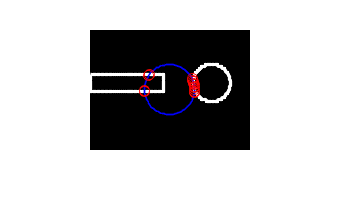

figure(4)
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    boundaries = bwboundaries(BW);
    
    % Define the center of the image (middle)
    [height, width] = size(BW);
    center_x = round(width / 2);
    center_y = round(height / 2);

    % Define the radius of the circle
    radius = 25;

    % Create the circle using parametric equations
    theta = linspace(0, 2*pi, 100);  % 100 points for smoothness
    circle_x = center_x + radius * cos(theta);
    circle_y = center_y + radius * sin(theta);
    
    % Ensure the circle coordinates stay within image boundaries
    circle_x = round(circle_x);
    circle_y = round(circle_y);

    % Extract contour points
    contour_points = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_points = [contour_points; boundary];  % Append all contour points
    end
    
    % Display the image with black background
    black_image = zeros(size(BW), 'like', BW);
    imshow(black_image);
    hold on;
    
    % Plot the contours in white
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2);  % Plot y, x coordinates in white
    end

    % Plot the circle outline in blue (using 'b' for blue)
    plot(circle_x, circle_y, 'b', 'LineWidth', 1);  % Blue circle
    
    % Find intersections using distance-based checking and mark them as red
    intersection_threshold = 1;  % Threshold for distance to detect intersections (in pixels)
    for idx = 1:length(circle_x)
        cx = circle_x(idx);
        cy = circle_y(idx);
        
        % Check if this point is within the threshold distance of any contour point
        distances = sqrt((contour_points(:,1) - cy).^2 + (contour_points(:,2) - cx).^2);
        if any(distances <= intersection_threshold)  % Check if any distance is below threshold
            plot(cx, cy, 'ro', 'MarkerSize', 6);  % Plot red point at intersection
        end
    end
    
    % Pause to display the result for a short time
    pause(0.2);
    
    hold off;
end

gay gay gay shit gówno 

% Binary mask for the current frame
BW = mask_img(:,:,30);  % Use the desired slice index

% Extract boundaries (no holes to avoid redundant processing)
boundaries = bwboundaries(BW, 'noholes');
fprintf('Number of boundaries: %d\n', length(boundaries));

Number of boundaries: 1



% Combine all contour points into a single array
contour_points = vertcat(boundaries{:});
fprintf('Number of contour points: %d\n', size(contour_points, 1));

Number of contour points: 380



% Downsample the contour points
downsample_rate = 10;  % Adjust for waypoint density
if downsample_rate <= size(contour_points, 1)
    waypoints_2d = contour_points(1:downsample_rate:end, :);
else
    waypoints_2d = contour_points;  % No downsampling if not enough points
end
fprintf('Number of waypoints: %d\n', size(waypoints_2d, 1));

Number of waypoints: 38


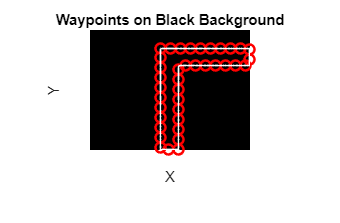


% Create a black image of the same size as BW
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Waypoints on Black Background');
xlabel('X'); ylabel('Y');
hold on;

% Plot the waypoints on the black image
plot(waypoints_2d(:,2), waypoints_2d(:,1), 'ro', 'MarkerSize', 6, 'LineWidth', 1.5);

% Optionally, plot the contours in white
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 1);  % White contours
end

hold off;

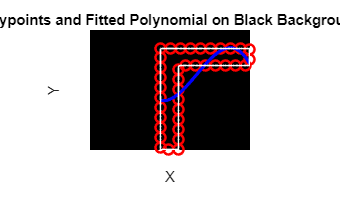

% Binary mask for the current frame
BW = mask_img(:,:,30);  % Use the desired slice index

% Extract boundaries (no holes to avoid redundant processing)
boundaries = bwboundaries(BW, 'noholes');

% Combine all contour points into a single array
contour_points = vertcat(boundaries{:});

% Downsample the contour points
downsample_rate = 10;  % Adjust for waypoint density
if downsample_rate <= size(contour_points, 1)
    waypoints_2d = contour_points(1:downsample_rate:end, :);
else
    waypoints_2d = contour_points;  % No downsampling if not enough points
end

% Separate x and y coordinates of waypoints
x = waypoints_2d(:,2);  % Column index is x-coordinate
y = waypoints_2d(:,1);  % Row index is y-coordinate

% Fit a 3rd-degree polynomial to the waypoints
p = polyfit(x, y, 3);

% Generate x-values for plotting the fitted curve
x_fit = linspace(min(x), max(x), 200);  % More points for a smooth curve

% Evaluate the polynomial to get the corresponding y-values
y_fit = polyval(p, x_fit);

% Create a black image of the same size as BW
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Waypoints and Fitted Polynomial on Black Background');
xlabel('X'); ylabel('Y');
hold on;

% Plot the waypoints in red
plot(x, y, 'ro', 'MarkerSize', 6, 'LineWidth', 1.5);

% Plot the fitted polynomial in blue
plot(x_fit, y_fit, 'b-', 'LineWidth', 2);

% Optionally, plot the contours in white
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 1);  % White contours
end

hold off;

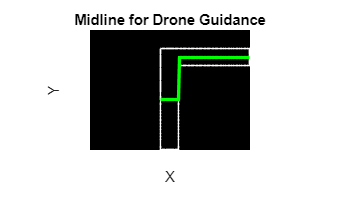

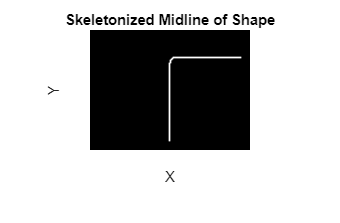

% Binary mask for the current frame (BW should be a binary image)
BW = mask_img(:,:,30);  % Use the desired slice index

% Apply morphological thinning to get the skeleton of the shape
skeleton = bwskel(BW, 'MinBranchLength', 5);  % You can adjust 'MinBranchLength' as needed

% Create a black image to visualize the result
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Skeletonized Midline of Shape');
xlabel('X'); ylabel('Y');
hold on;

% Plot the skeleton (midline) in white
[rows, cols] = find(skeleton);
plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points

hold off;

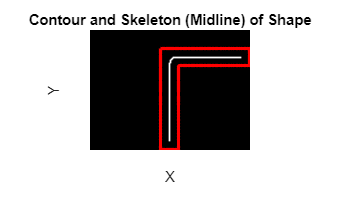

% Binary mask for the current frame (BW should be a binary image)
BW = mask_img(:,:,30);  % Use the desired slice index

% Apply morphological thinning to get the skeleton of the shape
skeleton = bwskel(BW, 'MinBranchLength', 5);  % You can adjust 'MinBranchLength' as needed

% Find the contours of the shape using bwboundaries
boundaries = bwboundaries(BW);

% Create a black image to visualize the result
black_image = zeros(size(BW), 'like', BW);

% Display the black image
figure;
imshow(black_image);
title('Contour and Skeleton (Midline) of Shape');
xlabel('X'); ylabel('Y');
hold on;

% Plot the skeleton (midline) in white
[rows, cols] = find(skeleton);
plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points

% Loop through each boundary and plot it in white (contours)
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
end

hold off;

HAHAHAHAHHAAHAHHAHAHA JEST KURWA 

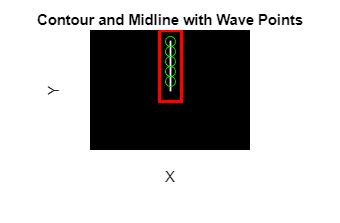

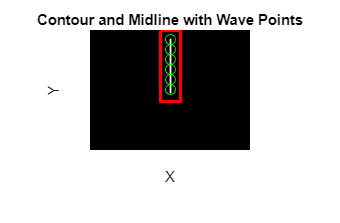

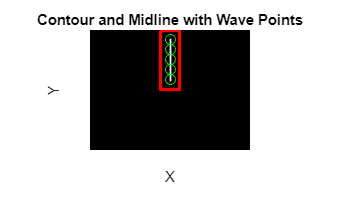

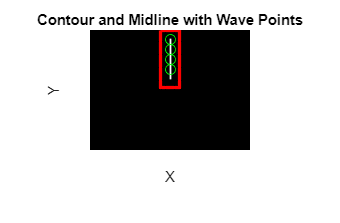

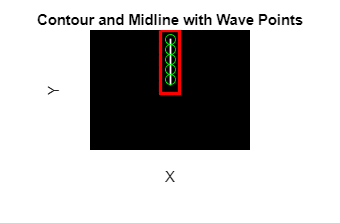

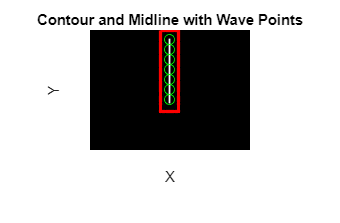

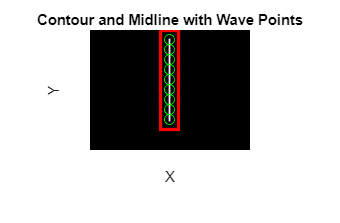

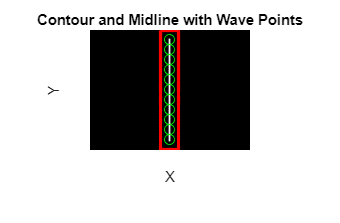

figure(4)
for sliceIdx = 5:101
    % Binary mask for the current frame (BW should be a binary image)
    BW = mask_img(:,:,sliceIdx);  % Use the desired slice index
    
    % Apply morphological thinning to get the skeleton of the shape
    skeleton = bwskel(BW, 'MinBranchLength', 5);  % You can adjust 'MinBranchLength' as needed
    
    % Find the contours of the shape using bwboundaries
    boundaries = bwboundaries(BW);
    
    % Create a black image to visualize the result
    black_image = zeros(size(BW), 'like', BW);
    
    % Display the black image
    figure;
    imshow(black_image);
    title('Contour and Midline with Wave Points');
    xlabel('X'); ylabel('Y');
    hold on;
    
    % Plot the skeleton (midline) in white
    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points
    
    % Select wave points by downsampling the skeleton (e.g., every 5th point)
    wave_points_interval = 10;  % Downsample interval (adjust as needed)
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);
    
    % Plot the wave points in green to reduce the number of elements
    plot(wave_points_cols, wave_points_rows, 'go', 'MarkerSize', 6);  % Green points
    
    % Loop through each boundary and plot it in red (contours)
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
    end
    
    hold off;
    pause(0.2)
end

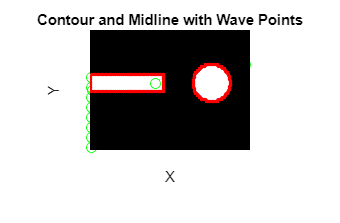

figure(4);  % Create figure once


% Loop over slices
for sliceIdx = 5:101
    % Binary mask for the current frame (BW should be a binary image)
    BW = mask_img(:,:,sliceIdx);  % Use the desired slice index
    
    % Apply morphological thinning to get the skeleton of the shape
    skeleton = bwskel(BW, 'MinBranchLength', 5);  % Adjust 'MinBranchLength' as needed
    
    % Find the contours of the shape using bwboundaries
    boundaries = bwboundaries(BW);
    
    % Create a black image to visualize the result, same size as BW
    black_image = BW;  % Use BW directly for overlaying

    % Plot the mask (BW) first (this ensures the background is always visible)
    imshow(black_image);  % Display the original mask
    hold on;  % Keep adding plots on top
    
    % Plot the skeleton (midline) in white
    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points
    
    % Select wave points by downsampling the skeleton (every 10th point)
    wave_points_interval = 10;  % Downsample interval
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);
    
    % Plot the wave points in green to reduce the number of elements
    plot(wave_points_cols, wave_points_rows, 'go', 'MarkerSize', 6);  % Green points
    
    % Loop through each boundary and plot it in red (contours)
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
    end
    
    % Pause a short time for animation
    pause(0.2);
end

% Set axis labels and title after the loop ends
title('Contour and Midline with Wave Points');
xlabel('X'); ylabel('Y');

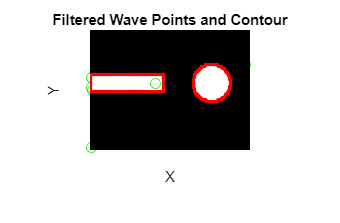

figure(5);
% Loop over slices
for sliceIdx = 5:101
    % Binary mask for the current frame (BW should be a binary image)
    BW = mask_img(:,:,sliceIdx);  % Use the desired slice index
    
    % Apply morphological thinning to get the skeleton of the shape
    skeleton = bwskel(BW, 'MinBranchLength', 5);  % Adjust 'MinBranchLength' as needed
    
    % Find the contours of the shape using bwboundaries
    boundaries = bwboundaries(BW);
    
    % Create a black image to visualize the result, same size as BW
    black_image = BW;  % Use BW directly for overlaying

    % Plot the mask (BW) first (this ensures the background is always visible)
    imshow(black_image);  % Display the original mask
    hold on;  % Keep adding plots on top
    
    % Plot the skeleton (midline) in white
    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);  % Plot the skeleton points
    
    % Select wave points by downsampling the skeleton (every 10th point)
    wave_points_interval = 10;  % Downsample interval
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);
    
    % Now filter out the redundant points based on the angle between them
    filtered_rows = [];
    filtered_cols = [];
    
    % Define a threshold for the angle change (in radians)
    angle_threshold = 5 * pi / 180;  % 5 degrees in radians

    for i = 1:length(wave_points_rows)-2
        % Calculate the vector from current point to the next
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];

        % Calculate the angle between the two vectors
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        % If the angle is greater than the threshold, keep the point
        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    % Add the first and last points explicitly
    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    % Plot the filtered wave points in green
    plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);  % Green points
    
    % Loop through each boundary and plot it in red (contours)
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);  % Plot the contours in red
    end
    
    % Pause a short time for animation
    pause(0.2);
end

% Set axis labels and title after the loop ends
title('Filtered Wave Points and Contour');
xlabel('X'); ylabel('Y');

figure(5);
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    skeleton = bwskel(BW, 'MinBranchLength', 5);
    boundaries = bwboundaries(BW);
    black_image = BW;

    imshow(black_image);
    hold on;

    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);

    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180;

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);

    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
    end

    pause(0.2);
end

title('Filtered Wave Points and Contour');
xlabel('X'); ylabel('Y');


figure(5);

% Initialize drone's starting position (center of the image)
drone_pos = [size(BW,1)/2, size(BW,2)/2];  % Middle of the current slice (image size)
FoV_angle = 30;  % Field of View in degrees
FoV_radians = deg2rad(FoV_angle);  % Convert to radians

for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    skeleton = bwskel(BW, 'MinBranchLength', 5);
    boundaries = bwboundaries(BW);
    black_image = BW;

    imshow(black_image);
    hold on;

    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);

    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180;

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);

    % Convert contour boundary to a polygon
    contour_x = [];
    contour_y = [];
    for k = 1:length(boundaries)
        boundary = boundaries{k};
        contour_x = [contour_x; boundary(:,2)];
        contour_y = [contour_y; boundary(:,1)];
    end
    
    % Simulate drone movement towards wave points, but only if they are within the contour
    for i = 1:length(filtered_rows)
        % Check if the current wave point is within the contour using inpolygon
        in_contour = inpolygon(filtered_cols(i), filtered_rows(i), contour_x, contour_y);
        
        % If the point is within the contour, proceed with the movement
        if in_contour
            % Calculate direction to current wave point from the drone
            direction_to_wp = [filtered_cols(i) - drone_pos(2), filtered_rows(i) - drone_pos(1)];

            % Plot line from drone to wave point (for visualization)
            plot([drone_pos(2), filtered_cols(i)], [drone_pos(1), filtered_rows(i)], 'b-', 'LineWidth', 2);

            % Move the drone towards the wave point
            drone_pos = [filtered_rows(i), filtered_cols(i)];

            % Plot the drone's current position
            plot(drone_pos(2), drone_pos(1), 'bo', 'MarkerSize', 8);
        end
        
        % Pause to simulate movement
        pause(0.2);
    end

    % Plot the boundaries of the object in red
    %for k = 1:length(boundaries)
        %boundary = boundaries{k};
        %plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
    %end
    
    pause(0.5);  % Pause to view the result of the current slice before moving to the next one
end

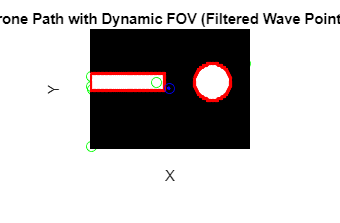

figure(5);
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    skeleton = bwskel(BW, 'MinBranchLength', 5);
    boundaries = bwboundaries(BW);
    black_image = BW;

    imshow(black_image);
    hold on;

    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);

    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180;

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);

    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
    end

    % Initialize drone's starting position at the center of the image
    drone_position = [size(BW, 1)/2, size(BW, 2)/2];

    % Initialize the first wave point as the target
    target_idx = 1;  % Starting with the first wave point
    target = [filtered_rows(target_idx), filtered_cols(target_idx)];

    % Drone's initial direction (towards the first wave point)
    direction_vector = target - drone_position;
    direction_vector = direction_vector / norm(direction_vector);

    % Plot the drone's initial direction
    quiver(drone_position(2), drone_position(1), direction_vector(2), direction_vector(1), ...
        'AutoScale', 'off', 'Color', 'b', 'LineWidth', 2, 'MaxHeadSize', 2);

    % Plot the drone's initial position
    plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 6);

    % Loop through the filtered wave points, starting from the second one
    for i = 2:length(filtered_rows)
        % Get the direction to the current wave point
        current_target = [filtered_rows(i), filtered_cols(i)];

        % Calculate the vector from the drone to the current wave point
        direction_to_target = current_target - drone_position;
        direction_to_target = direction_to_target / norm(direction_to_target);

        % Compute the angle between the drone's current direction and the direction to the target
        angle_to_target = acos(dot(direction_vector, direction_to_target));

        % Define the angle limit for the FOV (e.g., 45 degrees)
        fov_angle_limit = 45 * pi / 180;  % 45 degrees in radians

        if angle_to_target < fov_angle_limit
            % If the wave point is within the FOV, update the target
            target = current_target;
            direction_vector = direction_to_target;  % Update the drone's direction

            % Plot the new direction of view
            quiver(drone_position(2), drone_position(1), direction_vector(2), direction_vector(1), ...
                'AutoScale', 'off', 'Color', 'b', 'LineWidth', 2, 'MaxHeadSize', 2);

            % Plot the drone's new position
            plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 6);

            % Move the drone to the next wave point
            drone_position = target;  % Update the drone's position

            % Pause for animation effect
            pause(0.2);
        end
    end

    pause(0.5); % Pause between slices
end


% Set axis labels and title after the loop ends
title('Drone Path with Angle of View');
xlabel('X'); ylabel('Y');



figure(5);
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    skeleton = bwskel(BW, 'MinBranchLength', 5);
    boundaries = bwboundaries(BW);
    black_image = BW;

    imshow(black_image);
    hold on;

    [rows, cols] = find(skeleton);
    plot(cols, rows, 'w.', 'MarkerSize', 3);

    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180;

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);

    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
    end

    % Initialize drone's starting position at the center of the image
    drone_position = [size(BW, 1)/2, size(BW, 2)/2];

    % Initialize the first wave point as the target
    target_idx = 1;  % Starting with the first wave point
    target = [filtered_rows(target_idx), filtered_cols(target_idx)];

    % Drone's initial direction (towards the first wave point)
    direction_vector = target - drone_position;
    direction_vector = direction_vector / norm(direction_vector);

    % Define the angle for the cone (Field of View)
    fov_angle = 45 * pi / 180;  % Cone opening angle (45 degrees)

    % Plot the drone's initial position
    plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 6);

    % Draw the initial FOV cone (2 lines representing the cone boundaries)
    line_length = 100;  % Length of the lines representing the cone
    left_cone_vector = direction_vector;  % Left boundary vector
    right_cone_vector = direction_vector;  % Right boundary vector

    % Rotate the vectors by ±FOV angle to get the cone boundaries
    left_cone_vector = [cos(fov_angle) -sin(fov_angle); sin(fov_angle) cos(fov_angle)] * left_cone_vector';
    right_cone_vector = [cos(-fov_angle) -sin(-fov_angle); sin(-fov_angle) cos(-fov_angle)] * right_cone_vector';

    % Plot the cone boundaries
    quiver(drone_position(2), drone_position(1), left_cone_vector(1) * line_length, left_cone_vector(2) * line_length, ...
        'AutoScale', 'off', 'Color', 'g', 'LineWidth', 2, 'MaxHeadSize', 2);
    quiver(drone_position(2), drone_position(1), right_cone_vector(1) * line_length, right_cone_vector(2) * line_length, ...
        'AutoScale', 'off', 'Color', 'g', 'LineWidth', 2, 'MaxHeadSize', 2);

    % Loop through the filtered wave points, starting from the second one
    for i = 2:length(filtered_rows)
        % Get the direction to the current wave point
        current_target = [filtered_rows(i), filtered_cols(i)];

        % Calculate the vector from the drone to the current wave point
        direction_to_target = current_target - drone_position;
        direction_to_target = direction_to_target / norm(direction_to_target);

        % Compute the angle between the drone's current direction and the direction to the target
        angle_to_target = acos(dot(direction_vector, direction_to_target));

        % Define the angle limit for the FOV (within the cone)
        if angle_to_target < fov_angle
            % If the wave point is within the FOV, update the target
            target = current_target;
            direction_vector = direction_to_target;  % Update the drone's direction

            % Plot the new direction of view
            quiver(drone_position(2), drone_position(1), direction_vector(1) * line_length, direction_vector(2) * line_length, ...
                'AutoScale', 'off', 'Color', 'b', 'LineWidth', 2, 'MaxHeadSize', 2);

            % Plot the drone's new position
            plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 6);

            % Move the drone to the next wave point
            drone_position = target;  % Update the drone's position

            % Draw the updated FOV cone after moving to the next wave point
            left_cone_vector = direction_vector;
            right_cone_vector = direction_vector;
            left_cone_vector = [cos(fov_angle) -sin(fov_angle); sin(fov_angle) cos(fov_angle)] * left_cone_vector';
            right_cone_vector = [cos(-fov_angle) -sin(-fov_angle); sin(-fov_angle) cos(-fov_angle)] * right_cone_vector';
            
            % Plot the updated cone boundaries
            quiver(drone_position(2), drone_position(1), left_cone_vector(1) * line_length, left_cone_vector(2) * line_length, ...
                'AutoScale', 'off', 'Color', 'g', 'LineWidth', 2, 'MaxHeadSize', 2);
            quiver(drone_position(2), drone_position(1), right_cone_vector(1) * line_length, right_cone_vector(2) * line_length, ...
                'AutoScale', 'off', 'Color', 'g', 'LineWidth', 2, 'MaxHeadSize', 2);

            % Pause for animation effect
            pause(0.2);
        end
    end

    pause(0.5); % Pause between slices
end

% Set axis labels and title after the loop ends
title('Drone Path with FOV Cone');
xlabel('X'); ylabel('Y');

figure(5);
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx);
    skeleton = bwskel(BW, 'MinBranchLength', 5);
    boundaries = bwboundaries(BW);

    imshow(BW);
    hold on;

    [rows, cols] = find(skeleton);
    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180;

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);

    for k = 1:length(boundaries)
        boundary = boundaries{k};
        plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
    end

    % Initialize drone's starting position at the center of the image
    drone_position = [size(BW, 1)/2, size(BW, 2)/2];
    target_idx = 1;  % Starting with the first wave point
    target = [filtered_rows(target_idx), filtered_cols(target_idx)];
    direction_vector = target - drone_position;
    direction_vector = direction_vector / norm(direction_vector);

    % Define the angle for the cone (Field of View)
    fov_angle = 45 * pi / 180;  % 45 degrees
    line_length = 100;          % Length of cone boundary lines

    % Plot the initial drone position
    plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 6);

    % Loop through the filtered wave points
    for i = 2:length(filtered_rows)
        current_target = [filtered_rows(i), filtered_cols(i)];
        direction_to_target = current_target - drone_position;
        direction_to_target = direction_to_target / norm(direction_to_target);
        angle_to_target = acos(dot(direction_vector, direction_to_target));

        if angle_to_target < fov_angle
            % Clear previous FOV cone
            cla;  % Clear axes to remove old drawings

            % Redraw background elements
            imshow(BW);
            hold on;
            plot(filtered_cols, filtered_rows, 'go', 'MarkerSize', 6);
            for k = 1:length(boundaries)
                boundary = boundaries{k};
                plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 2);
            end

            % Plot the current drone position
            plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 6);

            % Draw the current FOV cone
            left_cone_vector = [cos(fov_angle) -sin(fov_angle); sin(fov_angle) cos(fov_angle)] * direction_vector';
            right_cone_vector = [cos(-fov_angle) -sin(-fov_angle); sin(-fov_angle) cos(-fov_angle)] * direction_vector';

            % Draw cone boundary lines
            plot([drone_position(2), drone_position(2) + left_cone_vector(2) * line_length], ...
                 [drone_position(1), drone_position(1) + left_cone_vector(1) * line_length], 'g', 'LineWidth', 2);
            plot([drone_position(2), drone_position(2) + right_cone_vector(2) * line_length], ...
                 [drone_position(1), drone_position(1) + right_cone_vector(1) * line_length], 'g', 'LineWidth', 2);

            % Update the drone's position and direction
            drone_position = current_target;
            direction_vector = direction_to_target;

            % Pause for animation
            pause(0.2);
        end
    end

    pause(0.5); % Pause between slices
end

% Set axis labels and title
title('Drone Path with Dynamic FOV Cone');
xlabel('X'); ylabel('Y');

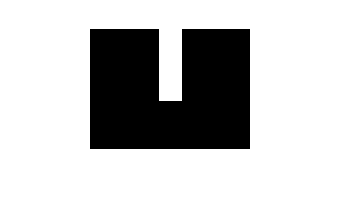

figure(5);

% Loop through each slice
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx); % Binary mask of the slice
    skeleton = bwskel(BW, 'MinBranchLength', 5); % Skeletonize the image
    [rows, cols] = find(skeleton); % Find skeleton points

    % Extract wave points
    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);
    wave_points = [wave_points_rows, wave_points_cols];

    % Initialize drone position (center of the image)
    drone_position = [size(BW, 1) / 2, size(BW, 2) / 2];
    fov_angle = 45 * pi / 180; % Field of view in radians
    fov_length = 100;          % Length of FOV lines
    direction_vector = [0, 1]; % Initial direction (facing "up")

    % Display the binary mask
    imshow(BW);
    hold on;

    % Draw wave points
    plot(wave_points(:,2), wave_points(:,1), 'go', 'MarkerSize', 6);

    % Main iteration to move the drone
    while ~isempty(wave_points)
        % Compute vectors from the drone to all wave points
        vectors_to_points = wave_points - drone_position;
        distances = vecnorm(vectors_to_points, 2, 2); % Compute distances
        vectors_to_points = vectors_to_points ./ distances; % Normalize

        % Compute angles between direction vector and wave points
        cos_angles = vectors_to_points * direction_vector';

        % Select points within FOV
        valid_indices = find(cos_angles > cos(fov_angle));
        if isempty(valid_indices)
            break; % Stop if no points are within FOV
        end

        % Get the closest wave point in FOV
        [~, closest_idx] = min(distances(valid_indices));
        selected_idx = valid_indices(closest_idx);
        next_point = wave_points(selected_idx, :);

        % Update FOV direction
        direction_vector = (next_point - drone_position) / norm(next_point - drone_position);

        % Draw current FOV (cone lines)
        left_cone_vector = [cos(fov_angle), -sin(fov_angle); sin(fov_angle), cos(fov_angle)] * direction_vector';
        right_cone_vector = [cos(-fov_angle), -sin(-fov_angle); sin(-fov_angle), cos(-fov_angle)] * direction_vector';
        plot([drone_position(2), drone_position(2) + left_cone_vector(2) * fov_length], ...
             [drone_position(1), drone_position(1) + left_cone_vector(1) * fov_length], 'g', 'LineWidth', 1.5);
        plot([drone_position(2), drone_position(2) + right_cone_vector(2) * fov_length], ...
             [drone_position(1), drone_position(1) + right_cone_vector(1) * fov_length], 'g', 'LineWidth', 1.5);

        % Draw line to the selected wave point
        plot([drone_position(2), next_point(2)], [drone_position(1), next_point(1)], 'b-', 'LineWidth', 2);

        % Update drone position
        drone_position = next_point;

        % Remove the visited wave point
        wave_points(selected_idx, :) = [];

        % Pause for visualization
        pause(0.2);

        % Clear FOV cone for the next iteration
        cla;
        imshow(BW);
        hold on;

        % Redraw remaining wave points
        plot(wave_points(:,2), wave_points(:,1), 'go', 'MarkerSize', 6);

        % Redraw visited path
        plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 8);
    end

    % Pause after completing one slice
    pause(0.5);
end

% Add title and labels
title('Drone Path with Dynamic FOV');
xlabel('X');
ylabel('Y');

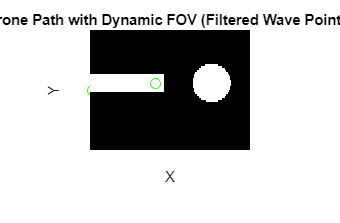

figure(5);

% Loop through each slice
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx); % Binary mask of the slice
    skeleton = bwskel(BW, 'MinBranchLength', 5); % Skeletonize the image
    [rows, cols] = find(skeleton); % Find skeleton points

    % Extract wave points at intervals
    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    % Filter wave points based on angle threshold
    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180; % Angle threshold in radians

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    % Add start and end points for completeness
    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    wave_points = [filtered_rows, filtered_cols]; % Reduced wave points

    % Initialize drone position (center of the image)
    drone_position = [size(BW, 1) / 2, size(BW, 2) / 2];
    fov_angle = 45 * pi / 180; % Field of view in radians
    fov_length = 100;          % Length of FOV lines
    direction_vector = [0, 1]; % Initial direction (facing "up")

    % Display the binary mask
    imshow(BW);
    hold on;

    % Draw wave points
    plot(wave_points(:,2), wave_points(:,1), 'go', 'MarkerSize', 6);

    % Main iteration to move the drone
    while ~isempty(wave_points)
        % Compute vectors from the drone to all wave points
        vectors_to_points = wave_points - drone_position;
        distances = vecnorm(vectors_to_points, 2, 2); % Compute distances
        vectors_to_points = vectors_to_points ./ distances; % Normalize

        % Compute angles between direction vector and wave points
        cos_angles = vectors_to_points * direction_vector';

        % Select points within FOV
        valid_indices = find(cos_angles > cos(fov_angle));
        if isempty(valid_indices)
            break; % Stop if no points are within FOV
        end

        % Get the closest wave point in FOV
        [~, closest_idx] = min(distances(valid_indices));
        selected_idx = valid_indices(closest_idx);
        next_point = wave_points(selected_idx, :);

        % Update FOV direction
        direction_vector = (next_point - drone_position) / norm(next_point - drone_position);

        % Draw current FOV (cone lines)
        left_cone_vector = [cos(fov_angle), -sin(fov_angle); sin(fov_angle), cos(fov_angle)] * direction_vector';
        right_cone_vector = [cos(-fov_angle), -sin(-fov_angle); sin(-fov_angle), cos(-fov_angle)] * direction_vector';
        plot([drone_position(2), drone_position(2) + left_cone_vector(2) * fov_length], ...
             [drone_position(1), drone_position(1) + left_cone_vector(1) * fov_length], 'g', 'LineWidth', 1.5);
        plot([drone_position(2), drone_position(2) + right_cone_vector(2) * fov_length], ...
             [drone_position(1), drone_position(1) + right_cone_vector(1) * fov_length], 'g', 'LineWidth', 1.5);

        % Draw line to the selected wave point
        plot([drone_position(2), next_point(2)], [drone_position(1), next_point(1)], 'b-', 'LineWidth', 2);

        % Update drone position
        drone_position = next_point;

        % Remove the visited wave point
        wave_points(selected_idx, :) = [];

        % Pause for visualization
        pause(0.2);

        % Clear FOV cone for the next iteration
        cla;
        imshow(BW);
        hold on;

        % Redraw remaining wave points
        plot(wave_points(:,2), wave_points(:,1), 'go', 'MarkerSize', 6);

        % Redraw visited path
        plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 8);
    end

    % Pause after completing one slice
    pause(0.5);
end

% Add title and labels
title('Drone Path with Dynamic FOV (Filtered Wave Points)');
xlabel('X');
ylabel('Y');

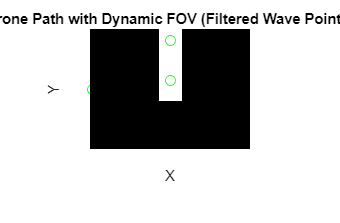

figure(5);

% Loop through each slice
for sliceIdx = 5:101
    BW = mask_img(:,:,sliceIdx); % Binary mask of the slice
    skeleton = bwskel(BW, 'MinBranchLength', 5); % Skeletonize the image
    [rows, cols] = find(skeleton); % Find skeleton points

    % Extract wave points at intervals
    wave_points_interval = 10;
    wave_points_rows = rows(1:wave_points_interval:end);
    wave_points_cols = cols(1:wave_points_interval:end);

    % Filter wave points based on angle threshold
    filtered_rows = [];
    filtered_cols = [];
    angle_threshold = 5 * pi / 180; % Angle threshold in radians

    for i = 1:length(wave_points_rows)-2
        vec1 = [wave_points_cols(i+1) - wave_points_cols(i), wave_points_rows(i+1) - wave_points_rows(i)];
        vec2 = [wave_points_cols(i+2) - wave_points_cols(i+1), wave_points_rows(i+2) - wave_points_rows(i+1)];
        angle = acos(dot(vec1, vec2) / (norm(vec1) * norm(vec2)));

        if angle > angle_threshold
            filtered_rows = [filtered_rows; wave_points_rows(i+1)];
            filtered_cols = [filtered_cols; wave_points_cols(i+1)];
        end
    end

    % Add start and end points for completeness
    filtered_rows = [wave_points_rows(1); filtered_rows; wave_points_rows(end)];
    filtered_cols = [wave_points_cols(1); filtered_cols; wave_points_cols(end)];

    wave_points = [filtered_rows, filtered_cols]; % Reduced wave points

    % Initialize drone position (center of the image)
    drone_position = [size(BW, 1) / 2, size(BW, 2) / 2];
    fov_angle = 45 * pi / 180; % Field of view in radians
    fov_length = 100;          % Length of FOV lines
    direction_vector = [0, 1]; % Initial direction (facing "up")

    % Display the binary mask
    imshow(BW);
    hold on;

    % Draw wave points
    plot(wave_points(:,2), wave_points(:,1), 'go', 'MarkerSize', 6);

    % Main iteration to move the drone
    while ~isempty(wave_points)
        % Compute vectors from the drone to all wave points
        vectors_to_points = wave_points - drone_position;
        distances = vecnorm(vectors_to_points, 2, 2); % Compute distances
        vectors_to_points = vectors_to_points ./ distances; % Normalize

        % Compute angles between direction vector and wave points
        cos_angles = vectors_to_points * direction_vector';

        % Select points within FOV
        valid_indices = find(cos_angles > cos(fov_angle));
        if isempty(valid_indices)
            break; % Stop if no points are within FOV
        end

        % Get the closest wave point in FOV
        [~, closest_idx] = min(distances(valid_indices));
        selected_idx = valid_indices(closest_idx);
        next_point = wave_points(selected_idx, :);

        % Update FOV direction
        direction_vector = (next_point - drone_position) / norm(next_point - drone_position);

        % Draw the FOV (cone lines) aligned to the next wave point
        left_cone_vector = [cos(fov_angle), -sin(fov_angle); sin(fov_angle), cos(fov_angle)] * direction_vector';
        right_cone_vector = [cos(-fov_angle), -sin(-fov_angle); sin(-fov_angle), cos(-fov_angle)] * direction_vector';

        plot([drone_position(2), drone_position(2) + left_cone_vector(2) * fov_length], ...
             [drone_position(1), drone_position(1) + left_cone_vector(1) * fov_length], 'g', 'LineWidth', 1.5);
        plot([drone_position(2), drone_position(2) + right_cone_vector(2) * fov_length], ...
             [drone_position(1), drone_position(1) + right_cone_vector(1) * fov_length], 'g', 'LineWidth', 1.5);

        % Draw line to the selected wave point
        plot([drone_position(2), next_point(2)], [drone_position(1), next_point(1)], 'b-', 'LineWidth', 2);

        % Update drone position
        drone_position = next_point;

        % Remove the visited wave point
        wave_points(selected_idx, :) = [];

        % Pause for visualization
        pause(0.2);

        % Clear FOV cone for the next iteration
        cla;
        imshow(BW);
        hold on;

        % Redraw remaining wave points
        plot(wave_points(:,2), wave_points(:,1), 'go', 'MarkerSize', 6);

        % Redraw visited path
        plot(drone_position(2), drone_position(1), 'bo', 'MarkerSize', 8);
    end

    % Pause after completing one slice
    pause(0.5);
end

% Add title and labels
title('Drone Path with Dynamic FOV (Filtered Wave Points)');
xlabel('X');
ylabel('Y');